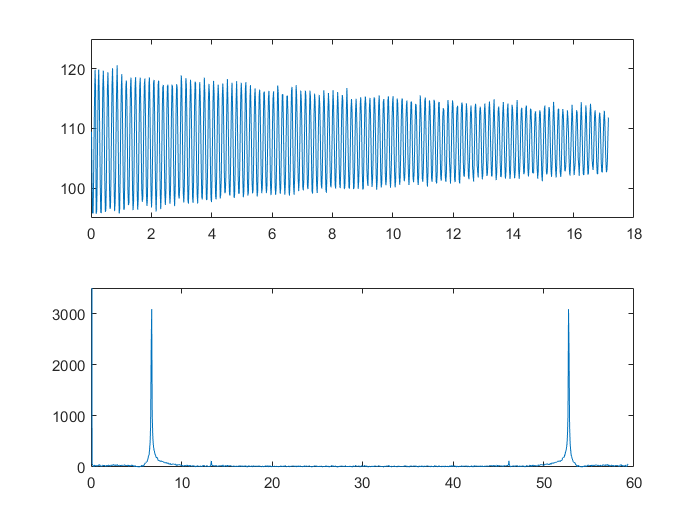

a = VideoReader('video.mp4');
k = a.NumFrames - 10;
Y_Coord = (1:k);
for N = 1:k
    I = readFrame(a);
    %figure,imshow(I)
    gray_I = rgb2gray(I);
    cropped = gray_I(50:450,550:1750);
    %imshow(cropped)
    bw_I = im2bw(cropped,0.51);
    %imshow(bw_I)
    bw_I = bwareaopen(bw_I,1000);
    %size(bw_I)
    se1 = strel('square',13);
    %se2 = strel('square',13);
    er = imerode(bw_I,se1);
    dil = imdilate(er,se1);
    final = dil(50:350,800:1200);
    final = bwareaopen(final,1000);
    s = regionprops(final,'Centroid');
    Y_Coord(N) = s.Centroid(1,2);
end
%Y_Coord;
subplot(211),plot((1:k)*17/1000,Y_Coord);
xlim([0.0 18.0])
ylim([95.0 125.0])
ff = fft(Y_Coord);
subplot(212),plot((1:k)*1/17,abs(ff))
ylim([0.0 3500.0])